% inputs
a = -3   % Left bracket

a = -3

b = 1   % Right bracket

b = 1

f = @(x) x^3  % function

f = function_handle with value:
    @(x)x^3


Text input 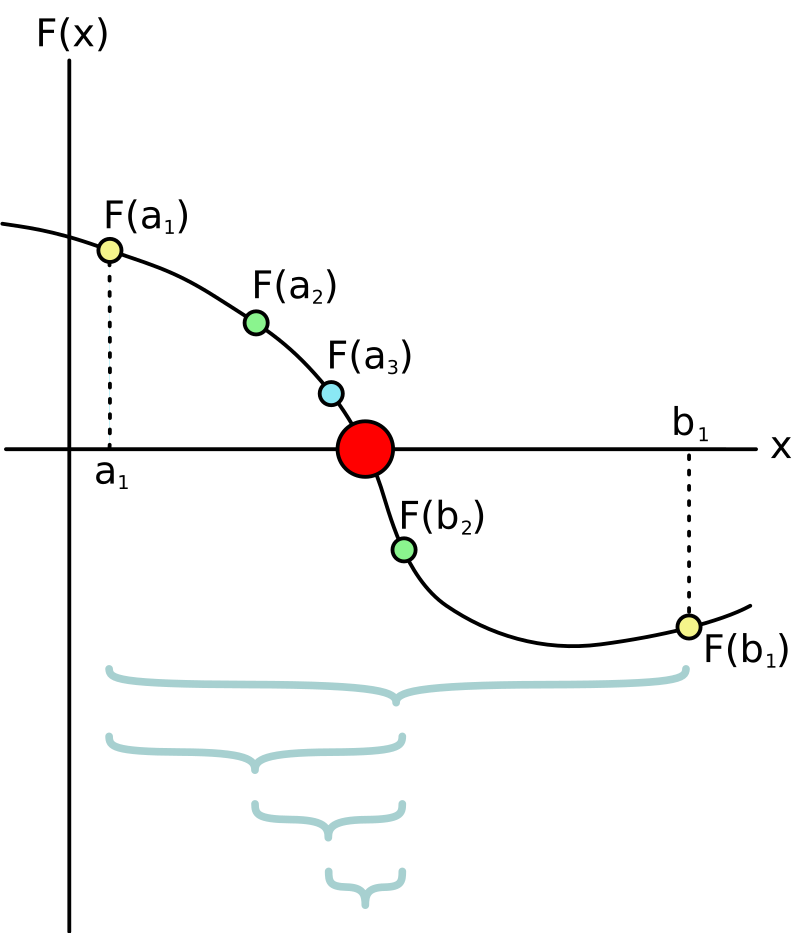[https://en.wikipedia.org/wiki/Bisection_method](https://en.wikipedia.org/wiki/Bisection_method)

fa = f(a)

fa = -27

fb = f(b)

fb = 1


% Checking for sign, if same sign, no root exists
if fa*fb > 0
    error('Root not bracketed in the interval')
end

% else continuing
c = (a+b)/2

c = -1

fc = f(c)

fc = -1


if fc == 0
    % Found the root exactly
    a = c
    b = c
    return
elseif fa*fc < 0
    % Root is in the interval [a,c]
    b = c
    fb = fc
else
    % Root is in the interval [c,b]
    a = c
    fa = fc
end

a = -1

fa = -1